# ENGR105    ---    Problem Set 8    ---   Text processing

## Due: Friday, 10/30/2020

## Name:

#### The University of Pennsylvania code of academic integrity can be found here:

[https://catalog.upenn.edu/pennbook/code-of-academic-integrity/](https://catalog.upenn.edu/pennbook/code-of-academic-integrity/)

By submitting this assignment, you certify that you completed this assignment in compliance with the code of academic integrity, as defined above, and that the work here is your own. Collaboration is allowed and encouraged but  it is in your own best interest to be able to complete all the problems on your own. Collaboration is allowed, COPYING is NOT. Be sure you are able to reason through each step. 

#### Notes on HW submission:

- Please save the final document In the following format: "<your last name>_<your first name>_HW8.mlx

- Run the entire document (`f5`) prior to submitting. Following this, please **export to .pdf** and **submit both** the .mlx file and the .pdf file to Canvas.

- The LiveScript file may be exported to PDF using the **Save** dropdown menu. **Please also see my recent email regarding alternative methods for exporting to PDF.**

- If it is not selected by default, select "Output Inline" at the top right of the LiveScript document to display the output below your code (rather than to the right).

#### Purpose of this problem set:

- Gain familiarity importing, analyzing, and processing text.

- Emphasize that many of the operations that we have worked with so far also apply to text.

- Analyze and work with a song that you enjoy!

#### Notes about MATLAB LiveScripts:

- The gray regions are "code" regions. Entering and running your code here is the same as running it in a `.m` script file or on the command line.

- "Running a piece of code" means you are executing the code in that section only. **Press **`Cntl`** + **`Enter`** to run a given section.**

- Press `f5` to run all sections of the document.

- To remove inline figures, right click and select "Clear All Output."

- When you run a section (each section refers to a different problem or part of a problem), all variables and vectors are stored in MATLAB and may be called from the command line.

**Reminder: Prior to submitting, be sure to run ****all**** sections of the document to ensure that it works properly. After running all sections, export the document to pdf.**

## PROBLEM 1 (100 pts): Processing musical lyrics

You have started a collaboration with the English Department to analyze the frequency of words used in popular culture. Specifically, the goal of your work is to analyze the evolution of language in music. To get started with this project, your first goal is to create a computational approach for analyzing musical lyrics. **You decide to get started by analyzing a song that you like.**

**a (10 points):** **Pick a song that ****you**** like**. Copy the lyrics into a **text file** and save it with an **appropriate file name**. Import the text information into this LiveScript document using the `importdata()` function and assign it to variable `p1_A`. **Display the song lyrics** after importing.

p1_A = importdata("LikeIWantYou.txt");



**Note 1**: You can pick any song you want. However, please make sure there are sufficient lyrics to analyze.

**Note 2**: Only the lyrics for the song should be in the text file. Do not include the song title, other information about the song, or any additional text.

**Note 3**: I have included a sample file, containing lyrics from a song that I like (Reserve, by Egzod). To help with troubleshooting, I will depict how the output from certain parts of this problem should look when operated on this file. This is only intended to help you with troubleshooting -- **you should complete this assignment by analyzing a song that ****you**** like**.

*For reference, here are the first four lines of the output when operated on Reserve:*

`    {'How do we know when we have reached our limit?'        }`

`    {'Rattling up, firing from all pistons'                  }`

`    {'And it seems like you can't go there'                  }`

`    {'And it seems like you can't focus'                     }`

**b)** In the current form, the cell array is not very useful for providing meaningul information. Convert the cell array `p1_A` into a** new cell array** where *each cell* contains a word. That is, there should be** one cell for every word in the song**. You should also:

- Remove all punctuation

- Make all words lower case

- Remove spaces

**Assign this new cell array **to variable `p1_B`. 


%remove punctuation 

% 
% %method for doing it for one line, need to mimic for the rest of the lines
% a = [' ',a, ' '];
% ind = (1:length(a)).*isspace(a);
% ind = ind(ind~=0);
% mywords = cell(1,length(ind)-1);
% 
% for k = 1:length(mywords)
%     mywords{k} = a(ind(k)+1:ind(k+1)-1);
% end
% disp(mywords);
p1_B = {};
for i = 1:length(p1_A)
    
    a = lower(p1_A{i});
    a = a(isspace(a) | isletter(a));   
%method for doing it for one line, need to mimic for the rest of the lines
    a = [' ',a, ' '];
    ind = (1:length(a)).*isspace(a);
    ind = ind(ind~=0);
    mywords = cell(1,length(ind)-1);
    %adds the different words into a new cell
    for k = 1:length(mywords)
        mywords{k} = a(ind(k)+1:ind(k+1)-1);
        p1_B(end+1) = mywords(k);
    end 
end


% for k = 1:length(p1_A)
%     a = split(p1_A{i});
%     
%     for k = 1:length(a)
%         p1_B(end+1) = a(k);
%     end


**Note**: there will probably be many cells containing the same word. That is to be expected. We will analyze word frequency in the next part.

*For reference, here are the first five entries of *`p1_B`* when operated on Reserve:*

`  Columns 1 through 5`

`    {'how'}    {'do'}    {'we'}    {'know'}    {'when'}`

**c)** In its current form, `p1_B` is a cell array containing every word in the song. However, we would really like to know *how often *a given word occurs. **Create a new cell array that only contains unique words**. Call this cell array `p1_C`. Also, **create a vector** `p1_C_counts` that stores the number of times the word in the corresponding position of `p1_C` occurs in the song.


p1_C = p1_B;
uniqueWord = {};
%create a cell that contains new unique words
p1_C_counts = ones(1,length(p1_B));
counter = 1;
%Step 1: Find the word and see if it repeats 
for k = 1:length(p1_B)
    uniqueWord = p1_B{k};
    
    %make the for loop to check if the previos word is equal to the current
    %word  
    for i = k+1:length(p1_B)
        if length(p1_B{i}) == length(uniqueWord) 
            if p1_B{i} == uniqueWord
                %delete the cell if same
                p1_C{i} = [];  
                %add to the couter for every time the word is equal to
                %itself 
                p1_C_counts(counter) = p1_C_counts(counter)+1;
            end
        end
        
    end
    counter = counter + 1;
end
p1_C = p1_C(not(cellfun('isempty', p1_C)));


%now need to only take the indices that are not empty
vec = [];
for jj = 1:length(p1_C)
    if ~(isempty(p1_C{jj}))
        vec(end+1) = jj;
    end
end

%disp(p1_C)
p1_C_counts = p1_C_counts(vec);

% for k = 1:length(p1_B)
%     for i = k+1:length(p1_C)
%      
%         if any(~isequal(p1_C{i}, p1_C{k}))
%             p1_C{1,end+1} = p1_B(i);
%            
%         end
%          
%     end
% end


*For reference, here are the first ten entries of *`p1_C_counts`* when operated on Reserve:*

`  Columns 1 through 10`

`     2     1     2     2    13     2     1     1     1     1`

**d)** **Create a bar graph** that summarize the song that you chose. That is, create a bar graph that has bars depicting each of these statistics:

- Number of lines

- Number of total words

- Number of unique words

- Number of letters

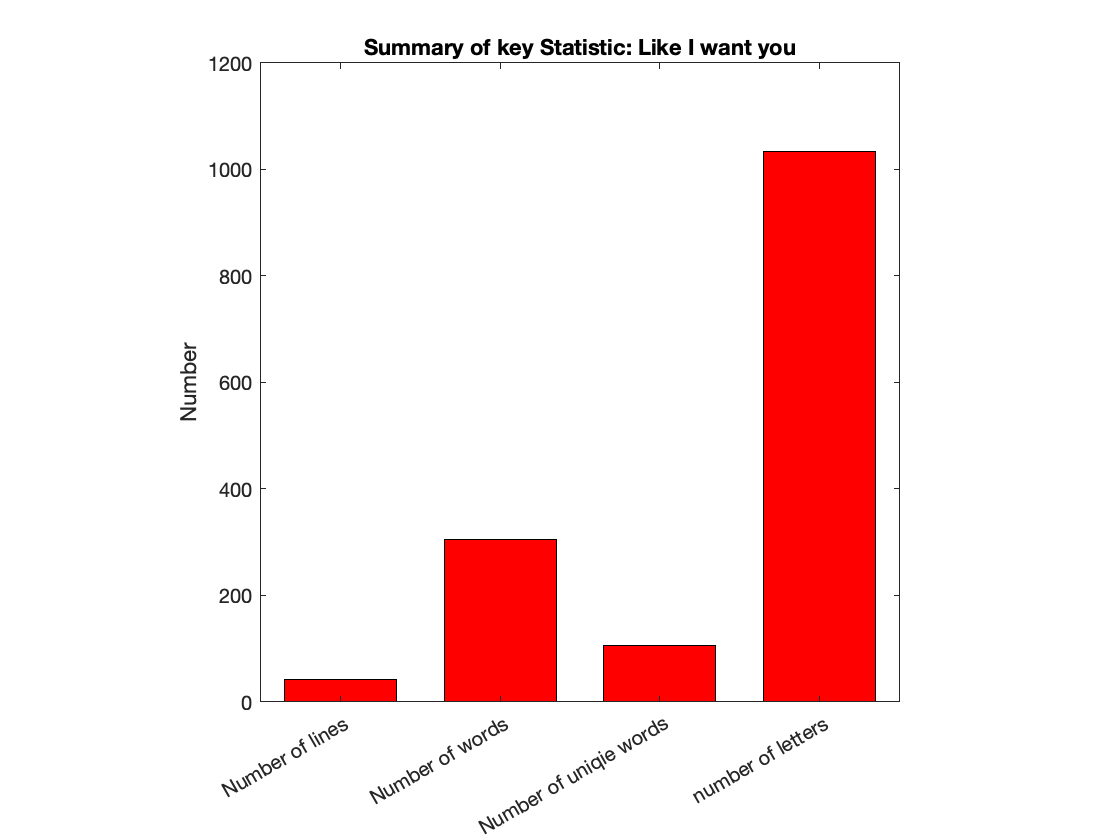

lines = length(p1_A);
wordcount = length(p1_B);
uniquewords = length(p1_C);
letters = sum(strlength(string(p1_B)));

x_val = {'Number of lines', 'Number of words', 'Number of uniqie words', 'number of letters'};
x_val2 = categorical(x_val);
x_val2 = reordercats(x_val2,x_val)';


bar(x_val2, [lines, wordcount, uniquewords, letters],0.7, 'r')
axis square 
ylabel('Number')
title('Summary of key Statistic: Like I want you')

b.EdgeColor = [0 0 0];

**Hint**: You should be able to obtain all of this information from your previously calculated p1_A, p1_B, p1_C

**Hint**: the MATLAB reference information for `bar()` may be useful.

**Hint**: regarding bar plots, you should input the "x variable" as a `categorical` data type. To reorder a `categorical` vector, please look at the help documentation for `reordercats()`

*For reference, here is the output from part ****d**** on Reserve:*

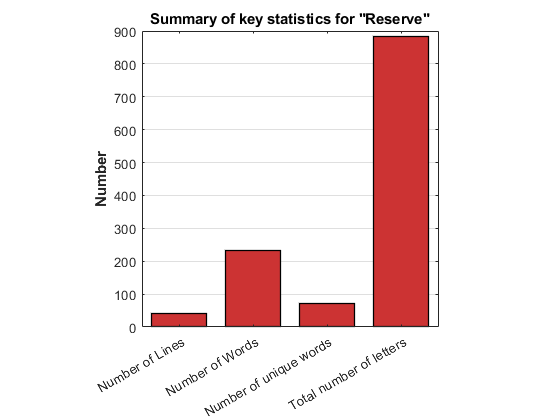

**e)** Next, you are interested in determining how many words contain each of the different **vowels**. **Create a bar plot** that depicts how many words in the song contain an "a","e","i","o", or "u."

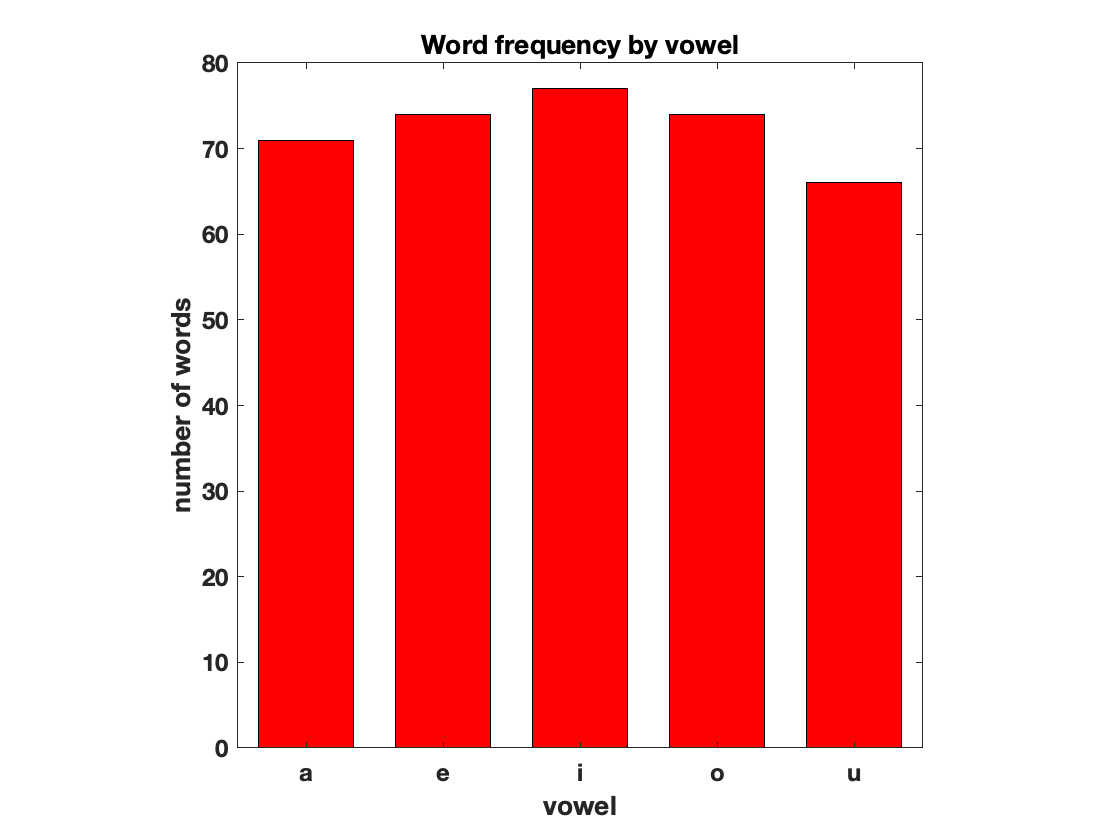

vowels = ['a', 'e', 'i', 'o', 'u'];
vowel_counter = zeros(1,5);
counter = 1;
for k = 1:length(p1_B)
   if strfind(p1_B{k},'a')
      vowel_counter(counter) = vowel_counter(counter) +1;
   end
   %counter = counter+1;
   if strfind(p1_B{k}, 'e')
      vowel_counter(counter+k) = vowel_counter(counter+1) +1; 
   end
   
   if strfind(p1_B{k}, 'i')
      vowel_counter(counter+2) = vowel_counter(counter+2) +1; 
   end
   
   if strfind(p1_B{k}, 'o')
      vowel_counter(counter+3) = vowel_counter(counter+3) +1; 
   end
   
   if strfind(p1_B{k}, 'u')
      vowel_counter(counter+4) = vowel_counter(counter+4) +1; 
   end
end


amount_a = vowel_counter(1);
amount_e = vowel_counter(2);
amount_i = vowel_counter(3);
amount_o = vowel_counter(4);
amount_u = vowel_counter(5);
 

x_val = {'a', 'e', 'i', 'o', 'u'};
x_val2 = categorical(x_val);
x_val2 = reordercats(x_val2,x_val)';
bar(x_val2, [amount_a, amount_o, amount_i, amount_o, amount_u], 0.7, 'r')
axis square
title('Word frequency by vowel')
ylabel('number of words')
xlabel('vowel')
set(gca, 'FontWeight', 'bold', 'FontSize', 12)

b.EdgeColor = [0 0 0];

*For reference, here is the output from part ****e ****on Reserve:*

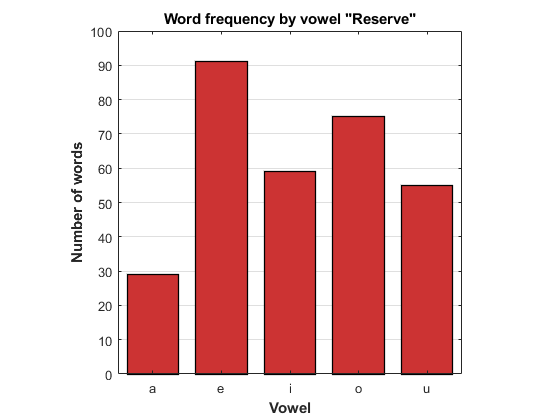

**f)** Starting with p1_C, **create a new cell array** that only contais **words that are at least 4 letters long** and that **appear in the song more than once**. Call this cell array `p1_F`. Also, **create a vector** `p1_F_counts` whose entries represent the number of times the corrsponding entries in `p1_F` appear in the song.


p1_F = {};
p1_F_counts = [];
counter = 1;
for k = 1:length(p1_C)
   
    if length(p1_C{k}) >= 4 && p1_C_counts(k) > 1
        p1_F{k} = p1_C{k};
        p1_F_counts(end+1) = p1_C_counts(k);
        
    end
    
end


p1_F = p1_F(not(cellfun('isempty', p1_F)));


**Hint**: the fastest way to do this may be to process `p1_C` and `p1_C_counts`, that were created above. The output from this problem will be a cell array and vector that are analagous to `p1_C` and `p1_C_counts`, but contain only the most common words (of at least 3 letters). 

**g)** Consider the words that **contain at least 4 letters** and **appear in your song** more than once. These are contained in `p1_F` and `p1_F_counts`, which you determined above.** Create a bar plot that depicts the number of times these "most common" words appear in your song**. Make sure the bar plot depicts the number of words in descending order.

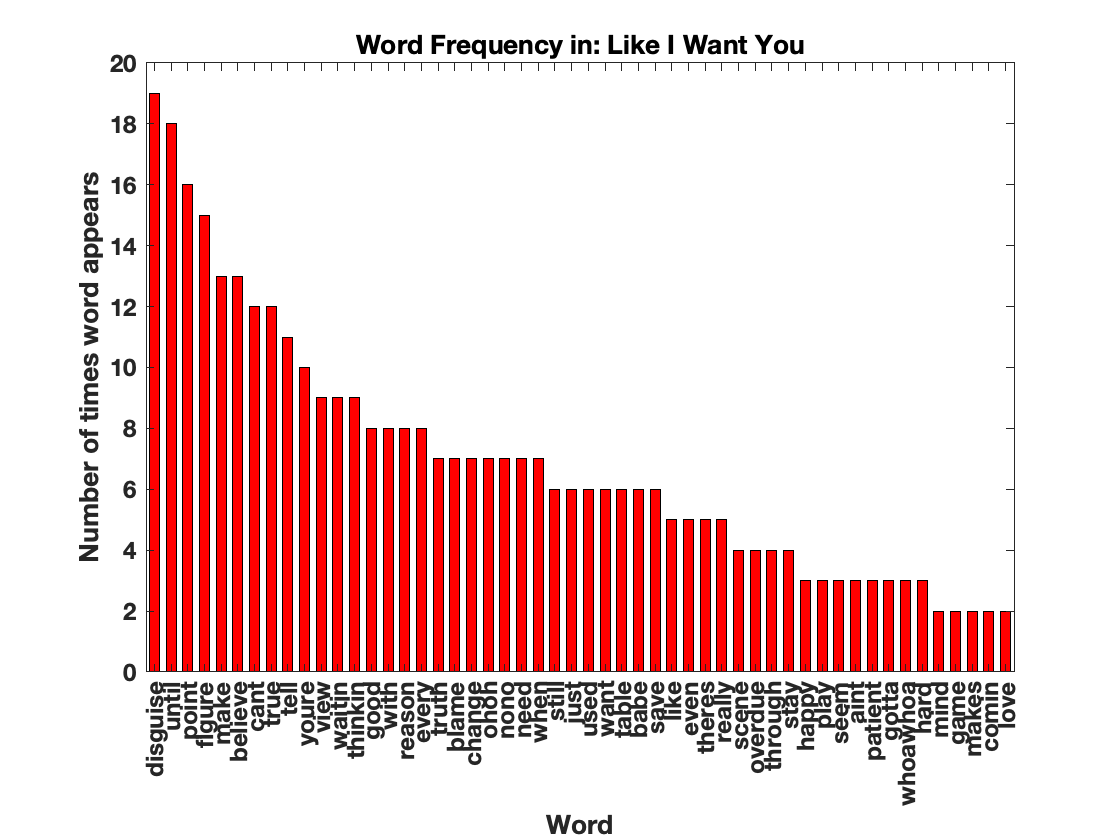

%I encodes how you sort it 


%Step 1: Sort pf_counts 
%Step 2: based on how you sort the first vector you should sort the second 
[sorted_p1_F_counts,I] = sort(p1_F_counts, 'descend');

sorted_p1_F = p1_F(I);
xval = sorted_p1_F;

xval2 = categorical(xval);

xval2 = reordercats(xval2,xval)';

yval = sorted_p1_F_counts;

bar(xval2, yval, 0.6, 'r')
ylabel('Number of times word appears')
xlabel('Word')
set(gca, 'FontWeight', 'bold', 'FontSize', 12)
title('Word Frequency in: Like I Want You')

b.EdgeColor = [0 0 0];


*For reference, here is the output from part ****g**** on Reserve:*

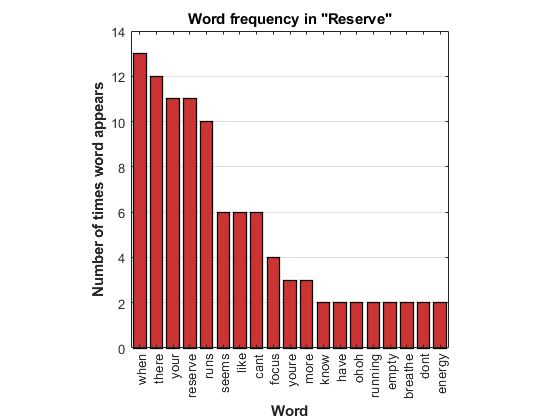

**h)** Finally, aside from bar plots (like what you created in **g**), **wordclouds** are a way to visually represent word frequency in a piece of text. In this case, the **relative size of the word is proportional to how frequently it occurs**. Using p1_F and p1_F_counts, **create a wordcloud using the built-in **`wordcloud`** function**. Play around with the formatting options for the graphics object and make it look however you want!

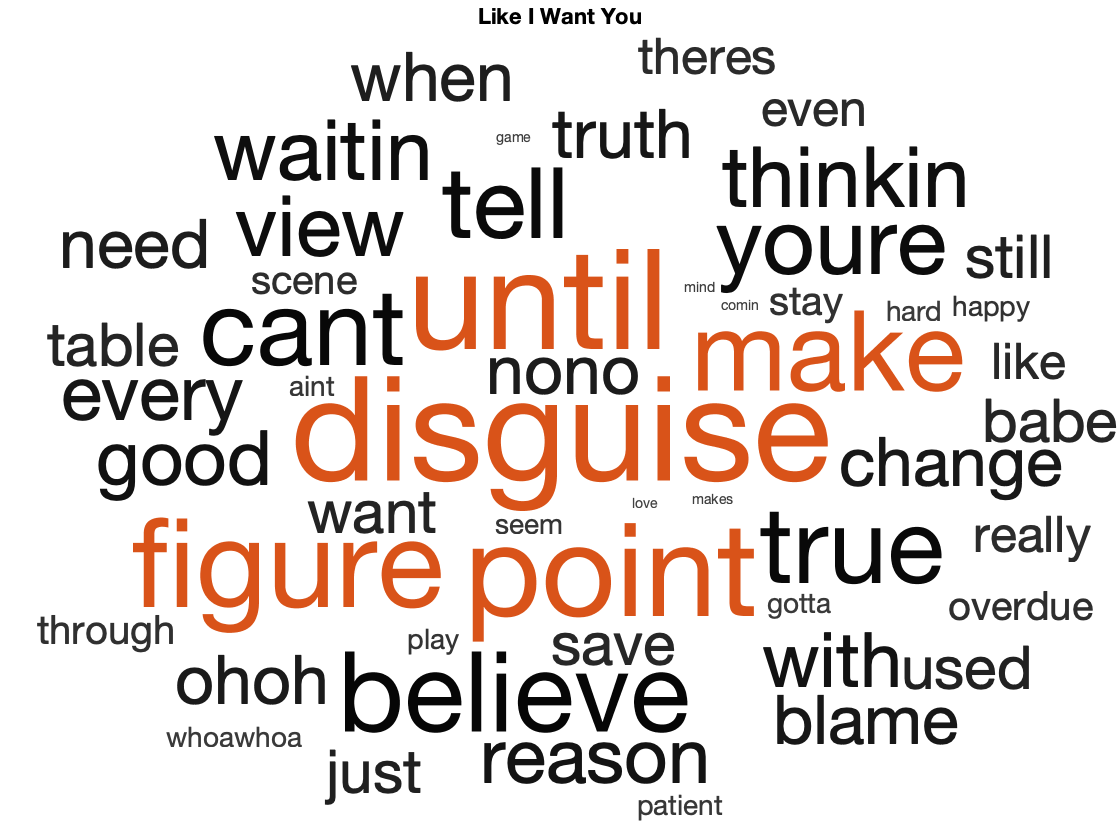

wordcloud(p1_F, p1_F_counts, 'Color', 'k')
title('Like I Want You')

*For reference, here is the output from part ****h**** on Reserve:*